# **Controller design for the motors**

clear
clc
close all

## **Motor parameters and t.f.**

First we define the motor paramters and it's transfer function

R = 4.1; 
L = 4.1e-3; 
Kb = 0.0074;
Kt = Kb; 
D = 0.93e-6; 
J = 1.01e-6;

Ts = 0.004;
transport_delay = 0.01;

Gn = Kt;
Gd = [J*L, D*L+J*R, D*R + Kt*Kb];
G = minreal(tf(Gn, Gd));
G.OutputDelay = transport_delay;
Gz = c2d(G, Ts,'zoh');

## PI Controller

Then we design the PI controller:

phase_margin = 75;
opts = pidtuneOptions('PhaseMargin', phase_margin); 
[C, info] = pidtune(Gz, 'PI', opts);
info

info = struct with fields:
                Stable: 1
    CrossoverFrequency: 26.1725
           PhaseMargin: 75.0000


Kp = C.Kp

Kp = 0.0154

Ki = C.Ki

Ki = 0.1771

s = tf('s');
C = Ki/s + Kp

C =
 
  0.0154 s + 0.1771
  -----------------
          s
 
Continuous-time transfer function.
Model Properties


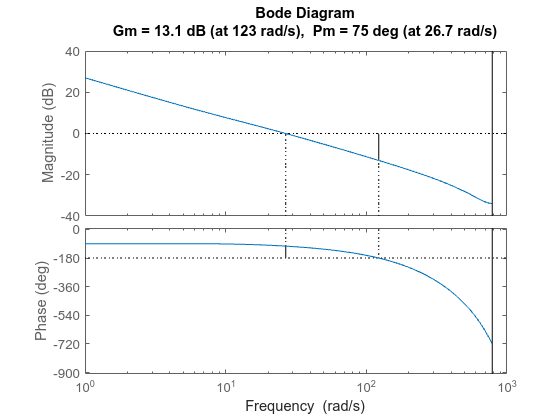

Cz = c2d(C, Ts, 'tunstin');

P = Cz*Gz;

figure; margin(P);

step(feedback(P,1), 5); 

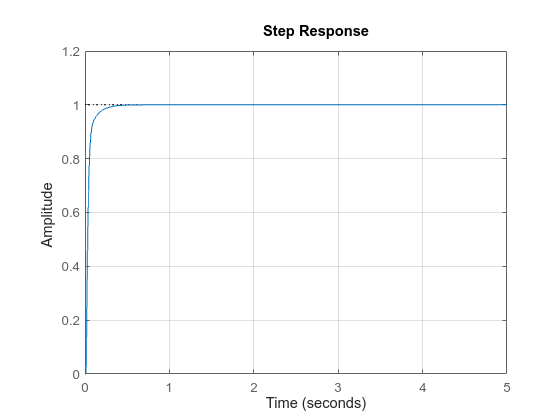

grid on;

save('motor_pi_gains', 'Kp', 'Ki');